directory = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\07_BilderNachSchildArt\5_Polygon_Schilder\Stoppschild";
cd(directory);      % Arbeitsverzeichnis setzen

imdsSchilder = imageDatastore(directory, "IncludeSubfolders", true, "LabelSource", "foldernames");

% outputFolder = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bilder\1_Runde_Schilder\Geschwindigkeitsempfehlungen\Geschwindigkeitsempfehlung 30\Bushaltestelle";

% a= exist(outputFolder, 'dir')
% 
% if a==0;
%     mkdir(outputFolder);
% end
% % 
% Jedes Bild durchlaufen, in Grau umwandeln und speichern
% for i = 1:numel(imdsSchilder.Files)
%     img = imread(imdsSchilder.Files{i});    % Bild laden
%     grayImg = rgb2gray(img);        % In Grau konvertieren
%     [~, filename, ext] = fileparts(imdsSchilder.Files{i}); % Dateiname extrahieren
%     imwrite(grayImg, fullfile(outputFolder, [filename, '_gray', ext])); % Speichern
% end
% imdsSchilderGrau = imageDatastore(outputFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");

Test Dreieckerkennunug

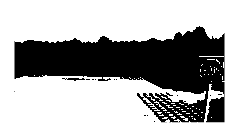

numVertices = 11

dateiname = 'C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\07_BilderNachSchildArt\5_Polygon_Schilder\Stoppschild\Stoppschild-2025-06-14__292.jpg'

j = 1

numVertices = 12

dateiname = 'C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\07_BilderNachSchildArt\5_Polygon_Schilder\Stoppschild\Stoppschild-2025-06-14__292.jpg'

j = 2

numVertices = 13

dateiname = 'C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\07_BilderNachSchildArt\5_Polygon_Schilder\Stoppschild\Stoppschild-2025-06-14__292.jpg'

j = 142

numVertices = 17

dateiname = 'C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\07_BilderNachSchildArt\5_Polygon_Schilder\Stoppschild\Stoppschild-2025-06-14__292.jpg'

j = 176

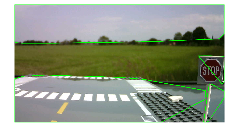


for i = 1:numel(imdsSchilder.Files)
    I = imread(imdsSchilder.Files{i});    % Bild laden
    figure; 
    imshow(I)
    grayImage = rgb2gray(I);
    imshow(grayImage)
    thresh = graythresh(grayImage); % automatische Schwellenwertbestimmung
    C = imbinarize(grayImage, thresh); % Schwarz-Weiß-Bild
     imshow(C)

    
    % Objekte labeln und Eigenschaften analysieren, Achtung hintergrund
    % pixel(Schwarz) werden als Hintergrund nicht als Objekt erkannt
    E = bwlabel(C); % Labeling der Objekte
    stats2 = regionprops(C, 'Area', 'Perimeter', 'BoundingBox', 'ConvexHull', 'Extrema');
    output = I;
    % Schleife durch erkannte Regionen
    zaehler = 0;
    % Toleranz für Eckenvereinfachung
    epsilon = 0.001;
    for j = 1:length(stats2)
        hull = stats2(j).ConvexHull;
        %Nur große genug Objekte weiterverarbeiten
        if stats2(j).Area > 500
            % Vereinfachung des Polygons, so das nur die Hauptpunkte die das Polygon 
            % ausmachen gefunden werden
            simplified = reducepoly(hull, epsilon);
            numVertices = size(simplified, 1)
            if numVertices >=9
                dateiname=imdsSchilder.Files{i}
                j
                % Möglicherweise ein Dreieck
                output = insertShape(output, 'Polygon', simplified, ...
                    'Color', 'green', 'LineWidth', 5);
            end
        end
    end
    figure; 
    imshow(output);
end